% PROJECT

% 3 DOF project

% From the computed D-H parameters, the robot is defined with three links

L(1) = Link([0, 10, 0, deg2rad(-90), 0]);
L(2) = Link([0, 0.5, 10, deg2rad(0), 0]);
L(3) = Link([0, 0.5, 10, deg2rad(0), 0]);

robot = SerialLink(L, 'name', 'wkk');
robot % Display the robot details

 
robot = 
 
wkk:: 3 axis, RRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         10|          0|    -1.5708|          0|
|  2|         q2|        0.5|         10|          0|          0|
|  3|         q3|        0.5|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


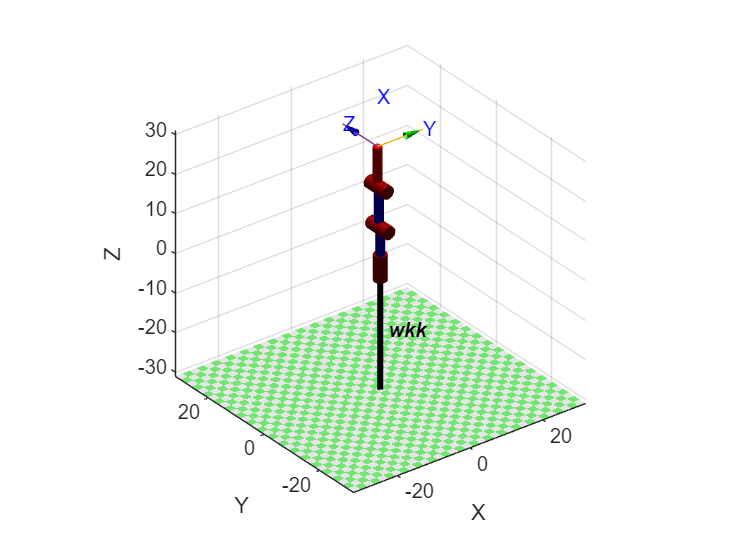


% Plot the robot at all angles = 0 radians
% This is my default robot's position
% robot.plot([0 0 0]); 

% Hold all plots here
figure;

home_position = [0, -1*pi/2, 0];
% subplot(2,2,1);
robot.plot(home_position);

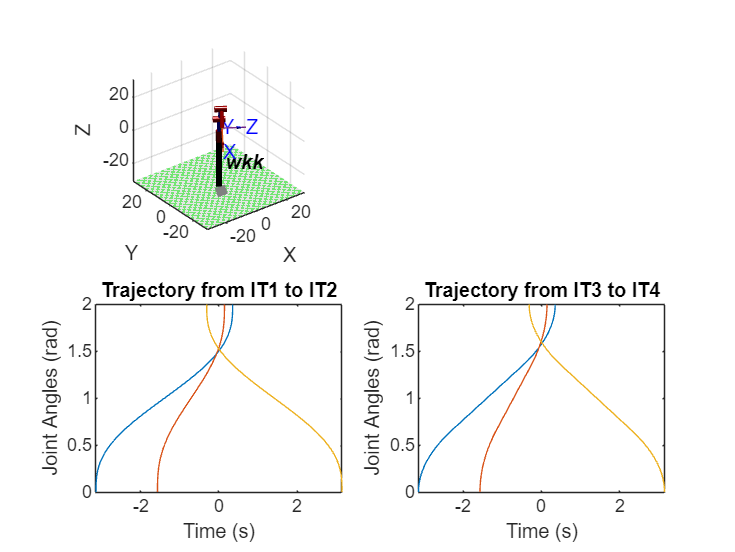

% title('Robot at Home Position');

% The mask option must be specified for under manipulated robots: i.e., robots with less than 6 DOF
% T = robot.fkine([pi/3, pi/4, pi/5]);
% IT = robot.ikine(T, 'mask', [1 1 1 0 0 0]);
% robot.plot(IT);

% Robot motion between two orientations in the space
% I need to find out why the below does not accept inverse kinematics
% Use a for loop to iterate over the forward kinematic to get the workspace limits
% T1 = transl(0.4, 0.2, 0) * trotx(pi);
% T21 = transl(-20, -2, 10) * trotx(pi/2); -> Does not  work because the robot is very under manipulated

T1 = robot.fkine([deg2rad(-180), deg2rad(-180), deg2rad(180)]);
T2 = robot.fkine([deg2rad(20), deg2rad(-10), deg2rad(18)]);
T3 = robot.fkine([deg2rad(-180), deg2rad(-180), deg2rad(180)]);
T4 = robot.fkine([pi, pi, pi]);

% The inverse kinematic of these is given by:
IT1 = robot.ikine(T1, 'mask', [1 1 1 0 0 0]);
IT2 = robot.ikine(T2, 'mask', [1 1 1 0 0 0]);
IT3 = robot.ikine(T1, 'mask', [1 1 1 0 0 0]);
IT4 = robot.ikine(T2, 'mask', [1 1 1 0 0 0]);

% Time for robot motion
t = [0:0.01:2]';

% Generate the trajectory using linear segments with parabolic blends
q = mtraj(@lspb, IT1, IT2, t);
q1 = jtraj(IT1, IT2, t); % Convenience function that is equivalent to mtraj with tpoly -> A higher order polynomial (Order 5)

%To obtain and plot all vectors - position, velocity and acceleration
q1 = jtraj(IT1, IT2, t);

subplot(2,2,3);
plot(q1, t);
title('Trajectory from IT1 to IT2');
xlabel('Time (s)');
ylabel('Joint Angles (rad)');

q = mtraj(@lspb, IT3, IT4, t);

subplot(2,2,4);
plot(q, t);
title('Trajectory from IT3 to IT4');
xlabel('Time (s)');
ylabel('Joint Angles (rad)');

% robot.jtraj(T1, T2, t, 'mask', [1 1 1 0 0 0])
subplot(2,2,1);
robot.plot(q1, 'loop');

title('Robot Motion from IT1 to IT2');
xlabel('X-axis');
ylabel('Y-axis');

% What we did above:
% Get the inverse kinematic angles theta 1 2 and 3
% Get T from the forward kinematic
% Plot a path using robot.jtraj with the T corresponding to the answer above
